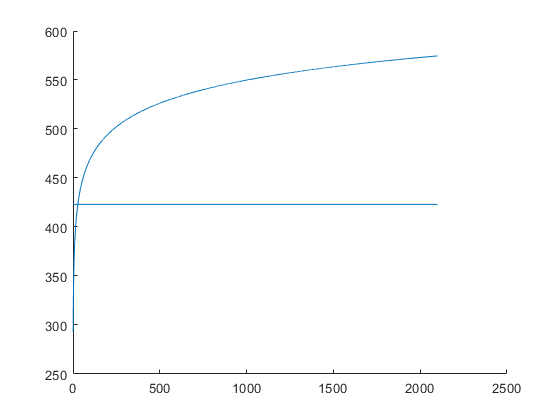

clc
clear all

Emanode=.2;%copper
Emchamber=.35;%ss
Sbcon=5.670373e-8; %W*m^-2*K^-4
x=linspace(1,2100,8400);
%K
T1= 1679.31+(-22252.17-1659.31)./(1+(x./1.881098e-39).^0.03126938);
Tmax=150+273.15*ones(length(x));
hold on
plot(x,T1)
plot(x,Tmax)

T2=298.15;
w=30*.0254;%"
h=50*.0254;%"
R=linspace(w,45*.0254,100);
%lanode=sym('Lanode');
lanode=.0508;
%ranode=sym('Ranode');
ranode=.0254;

for i=1:length(R)
for j=1:length(x)
A2=(pi*(w+h)/2)*lanode*3;
A1=pi*ranode*lanode;
F(i,j)=A2./(pi.*R(i).^2);
Den(i,j)=(1-Emanode)./(A1.*Emanode)+1./(A1.*F(i,j))+(1-Emchamber)./(A2.*Emchamber./2);
Q(i,j)=(Sbcon.*(T1(j).^4-T2.^4))./(Den(i,j));
tREM(i,j)=T1(j)-Q(i,j);
j=j+1;
end
i=i+1;
end


## conduction

%kaclculations
k0=14.3/293.15;
ki=k0.*T1;
T2=80+273.15;
T2alt=150+273.15;
T1=@(x) 1679.31+(-22252.17-1659.31)./(1+(x./1.881098e-39).^0.03126938);
Tmax= @(x) 150+273.15;
TT=T1-Tmax;

Undefined operator '-' for input arguments of type 'function_handle'.

[pos]=fzero(TT);